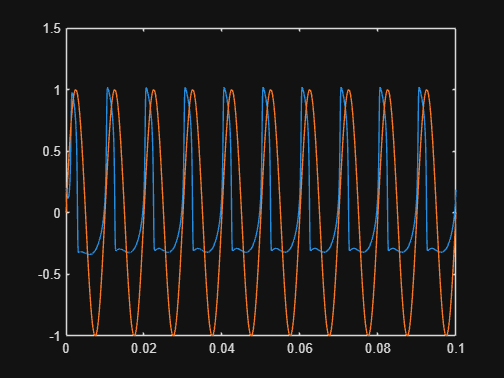

params.Tau = 2100.00;
params.TauR = 1500.00;
params.gc = 9.00;
params.NaX = 0.70;
params.alpha = 8.00;
params.b = 1.00;
% params.Tau = 2100;  % Neural time constant
% params.TauR = 1500;  % Recovery time constant
% params.gc = 9; % Conductance between compartments
% params.NaX = .7; % Sodium channel density factor for dendrites
% params.alpha = 8;
% params.b = 1;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Parameter adjustments for single neuron simulation (without dendritic tree)
paramsSingleNeuron = params;
paramsSingleNeuron.NaX = 1; % Always 1
paramsSingleNeuron.gc = 0;  % Conductance is 0 since no connections

% Initial conditions
initCon = [0.2; 0.2];

soma = Dendrite(0, paramsSingleNeuron, initCon);             
                                 
tree = DendriteTreeModel();                    
tree.addDendrite(soma);

tmax = 0.1;
h = 1e-5;

t = 0:h:tmax;
sig = sin(2*pi*100*t);
tree.addStimuli(0, sig);

tree.verify();

[~, sol] = RK4CPP(tree, tmax, h);

plot(t, [sol(1, :); sig])